# Lab Activity 8

#### ### Agam Goyal ###

## Prepare Workspace

close all
clear

load lab8dat.mat

## Item 2

b = [ 1 1 1 1 1 ]/5;

% Use the filter command to compute the convolution
y = filter(b,1,x1);

nstart = 25;
nstop = 66;

n = nstart:nstop;

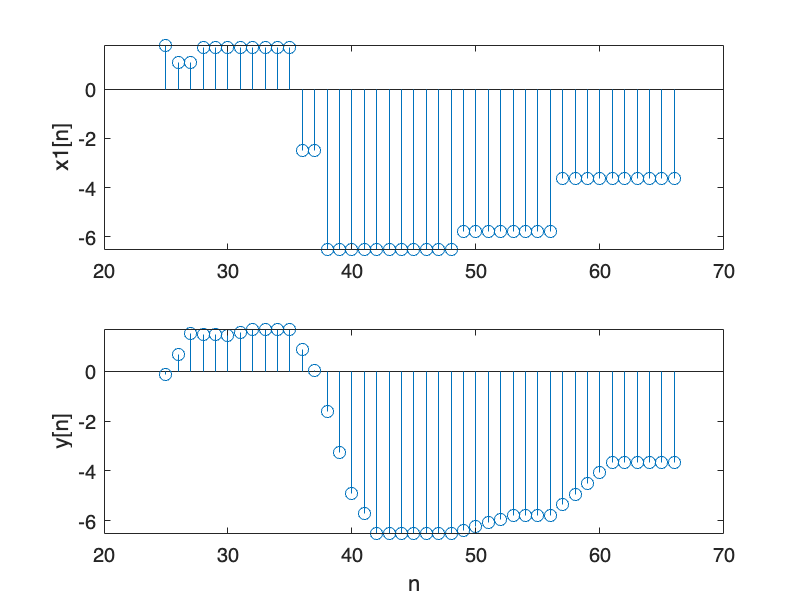

% Plotting 
figure
subplot(211)
stem(n, x1(n+1))  % offset by 1 since MATLAB starts indexing at 1, not 0
ylabel('x1[n]')
subplot(212)
stem(n,y(n+1))
ylabel('y[n]')
xlabel('n')

## Item 3

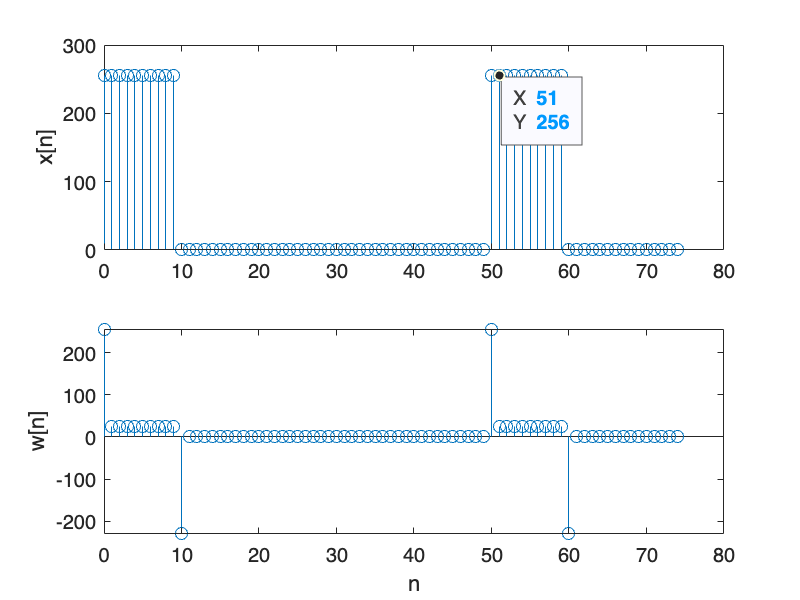

x = 256*(rem(0:100,50)<10);

r = 0.9;
b = [1 -r];
w = filter(b,1,x);
 
nstart = 0; 
nstop = 74; 
n = nstart:nstop;

figure
subplot(211)
stem(n, x(n+1))  % offset by 1 since MATLAB starts indexing at 1, not 0
ylabel('x[n]')
subplot(212)
stem(n,w(n+1))
ylabel('w[n]')
xlabel('n')

## Item 4

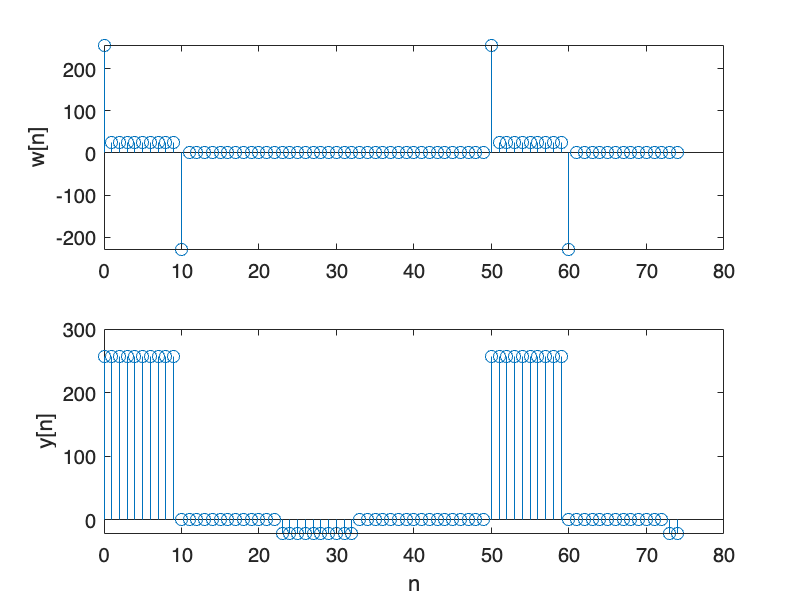

r = 0.9;
M = 22;

b_deconv = r.^[0:M];

y = filter(b_deconv,1,w);
 
nstart = 0; 
nstop = 74; 
n = nstart:nstop;

figure
subplot(211)
stem(n, w(n+1))  % offset by 1 since MATLAB starts indexing at 1, not 0
ylabel('w[n]')
subplot(212)
stem(n,y(n+1))
ylabel('y[n]')
xlabel('n')

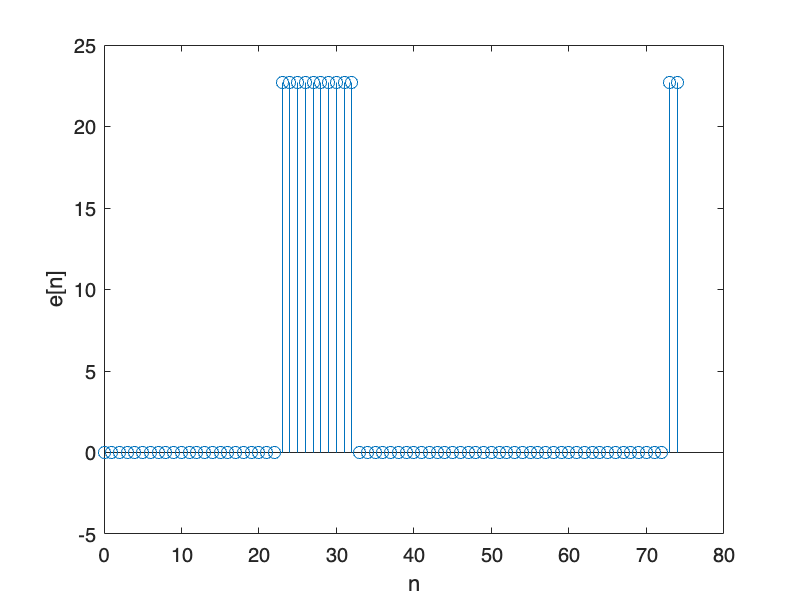


% Plotting the residual error.
e = x-y;

figure
stem(n,e(n+1))
ylabel('e[n]')
xlabel('n')


maxerr = max(abs(e))

maxerr = 22.6891